# Load raw data

%load("Pancake3Cropped.mat")
addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\ExtractClouds");
p3TotalCake = pcread("p3TotalCake.ply");

# Display raw data

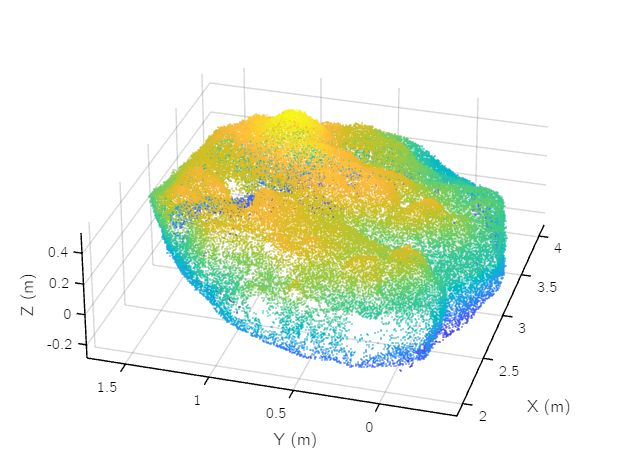

pcDisplay(p3TotalCake)

# Removing complexity

### Option 1: Downsample the clouds directly

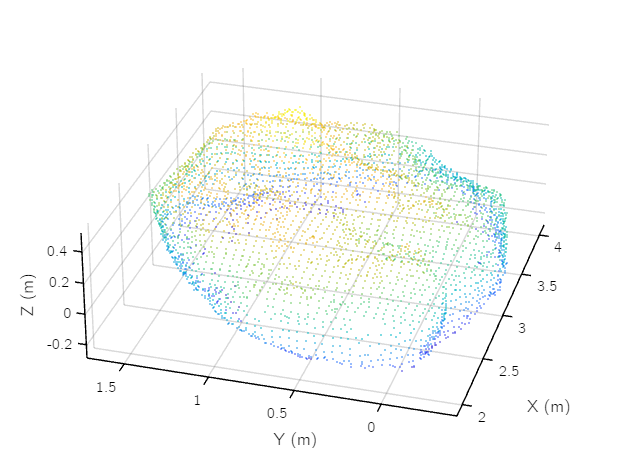

pcCleaned=pcdownsample(p3TotalCake,"gridAverage",0.05); %grid step of 5cm example
pcDisplay(pcCleaned)

### Option 2: decreasing depth

depth = 5; %depth of octree: depth between 4 and 6 reccomended based on processed data
%Using downsampled cloud
%mesh = pc2surfacemesh(pcCleaned,"poisson",depth);

%Using raw cloud
mesh = pc2surfacemesh(p3TotalCake,"poisson",depth);
surfaceMeshShow(mesh)

# Exporting

writeSurfaceMesh(mesh,"Pancake3Depth5.stl")

Once exported, 

- open the stl file in **PrusaSlicer**

- It will ask you to change from mm to inches (the data is actually in meters but it scales down fine) say yes

- On the right you can right click on the stl file and select **"Fix through the Netfabb"** - this closes up any holes

- Export your stl file :) 